# Interpolarea Lagrange

    Interpolarea Lagrange este o metoda matematica folosita pentru a construi u**n polinom care trece exact printr-un set de puncte cunoscute**. Scopul este de **a aproxima o functie necunoscuta** sau greu de calculat, folosind doar cateva valori ale acesteia in anumite puncte numite noduri

    Metoda se bazeaza pe **polinoame fundamentale** care sunt construite astfel incat fiecare dintre ele are valoarea 1 intr-un singur nod si 0 in celelalte. Acestea sunt combinate pentru a obtine polinomul de interpolare final

**Caracteristici principale**

- Este o metoda **directa** si **determinista** pentru un set de puncte exista un singur polinom de graf n care le uneste

- Nu necesita rezolvarea unui sistem de ecuatii

- Usor de implementat pentru un numar mic de puncte

- Devine **ineficienta** sau** instabila numeric** daca se folosesc multe puncte sau noduri echidistante (fenomenul Runge)

Fie nodurile x0,x1,x2... și valorile asociate f(x0),f(x1),…,f(xn). Polinomul de interpolare este:


$$\begin{array}{l}
L_n \left(x\right)=\sum_{k=0}^n f\left(x_k \right)*l_k \left(x\right),\mathrm{unde}\\
l_i \left(x\right)=\prod_{j=0,j\not= i} \frac{x-x_i }{x_i -x_j }
\end{array}$$


Fiecare $l_k \left(x\right)$ este un polinom fundamental, care este 1 in punctul k si 0 in rest

**Limitari**

- Fiecare adaugare a unui nou punct necesita recalcularea intregului polinom.

- Cresterea numarului de noduri duce la **instabilitate numerica** si erori mari în marginea intervalului (vezi efectul Runge).

- Ineficientă pentru aplicatii de timp real sau date in continua schimbare.

## Interpolarea Lagrange

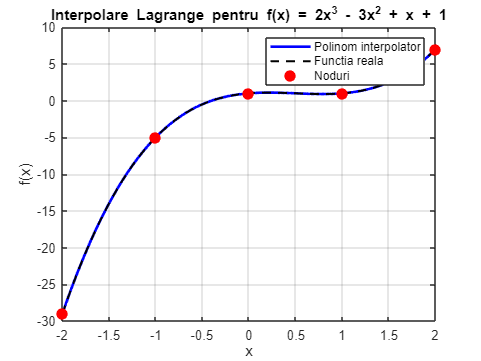

% Definim functia reala
f = @(x) 2*x.^3 - 3*x.^2 + x + 1;

% Alegem nodurile de interpolare
x_nodes = linspace(-2, 2, 5);  % 5 noduri => grad max 4 pentru interpolare

% Calculam valorile functiei in noduri
y_nodes = f(x_nodes);

% Puncte in care evaluam polinomul
x_eval = linspace(min(x_nodes), max(x_nodes), 300);

% Calculam valorile polinomului de interpolare
[p_val, p_expr] = Lagrange(x_nodes, y_nodes, x_eval);

% Afisam graficul
figure;
plot(x_eval, p_val, 'b-', 'LineWidth', 2); hold on;
fplot(f, [min(x_nodes), max(x_nodes)], 'k--', 'LineWidth', 1.5); % functia reala
plot(x_nodes, y_nodes, 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
grid on;
title('Interpolare Lagrange pentru f(x) = 2x^3 - 3x^2 + x + 1');
xlabel('x'); ylabel('f(x)');
legend('Polinom interpolator', 'Functia reala', 'Noduri');


% Afisam si polinomul simbolic in consola
disp('Polinomul Lagrange gasit:');

Polinomul Lagrange gasit:


pretty(p_expr);

   3      2
2 x  - 3 x  + x + 1



## Plotarea polinoamelor de baza Lagrange:

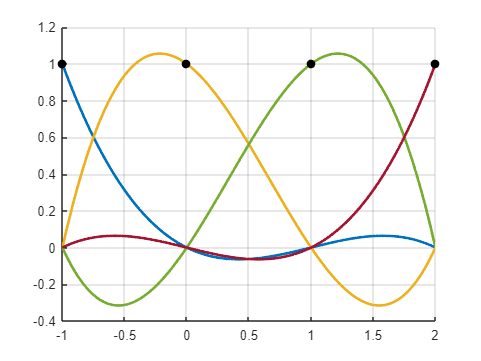

x_nodes = [-1, 0, 1, 2];
plotPolinoameFundamentale(x_nodes);

# **Interpolarea baricentrica**

    Interpolarea bericentrica este o tehnica matematica folosita pentur a aproxima o functie data pe un interbal folosind un polinom care trece printr un set de puncte date. Aceasta tehnica se baseaza pe ponderi care se calculeaza pt fiecare nod de interpolare

    Metoda baricentrica este forma **imbunatatia a interpolarii Lagrange**

**Formula:**


$$w_j =\frac{1}{\prod_{k=0,k\not= j}^n \left(x_j -x_k \right)}$$


**Formula baricentrica:** $p\left(x\right)=\frac{\sum_{j=0}^n \frac{w_j }{x-x_j }*f\left(x_j \right)}{\sum_{j=0}^n \frac{w_j }{x-x_j }}$

# Nodurile Cebisev de #1 si #2 

    Sunt puncte speciale care ajuta la construirea unui polinom de interpolare mai precis, minimizand erorile de aproximare. Distribuirea lor reduce efectele fenomenului numit "**eroare de Runge**", care poate aparea atunci cand folosim noduri uniform distribuite, mai ales in cazul functiilor care nu sunt foarte simple. Prin alegerea nodurilor Cebisev, interpolarea debine mai eficienta si mai exacta, minimizan erorile.

## **Nodurile Cebisev de #1**

    Acestea sunt punctele folosite în interpolarea baricentrică pentru a obține o aproximare mai bună a funcției pe care vrem să o interpolăm. Nodurile Cebisev de #1 sunt calculate folosind formula:

###  
$$x_i =\cos \left(\frac{\left(2i-1\right)\pi }{2n}\right),i=1,2,\ldotp \ldotp ,n$$


Aceste noduri sunt distribuite în intervalul [−1,1], dar nu sunt distribuite uniform. Ele sunt mai dense spre marginile intervalului și mai rare în centru.

### Interpolare baricentrica Lagrange cu noduri Chebyshev I

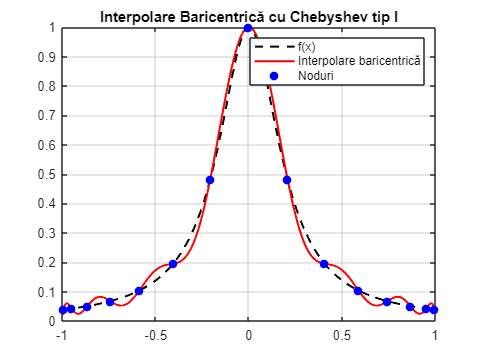

f = @(x) 1 ./ (1 + 25 * x.^2);
a = -1; b = 1; n = 15;

% Tipul nodurilor: 'I' sau 'II'
[xn, yn, w, xe, yeval, expr] = BaricentricaChebyshev(f, a, b, n, 'I');

% Plot
figure;
plot(xe, f(xe), 'k--', 'LineWidth', 1.5); hold on;
plot(xe, yeval, 'r-', 'LineWidth', 1.5);
plot(xn, yn, 'bo', 'MarkerFaceColor', 'b');
legend('f(x)', 'Interpolare baricentrică', 'Noduri');
title('Interpolare Baricentrică cu Chebyshev tip I');
grid on;

## **Nodurile Cebisev de #2**

    Aceste noduri sunt o variantă de noduri Cebisev de #1 și sunt folosite în unele cazuri pentru a optimiza interpolarea. Formula pentru calculul lor este similară, dar nodurile Cebisev de #2 sunt definite astfel încât să fie distribuite uniform în intervalul [−1,1][-1, 1][−1,1] în ceea ce privește ponderile lor (nu pozițiile lor). Practic, nodurile sunt ajustate astfel încât să minimizeze erorile de aproximare. 

### 
$$x_i =\cos \left(\frac{i\pi }{n+1}\right),i=1,2,\ldotp \ldotp ,n$$


### Interpolare baricentrica Lagrange cu noduri Chebyshev I

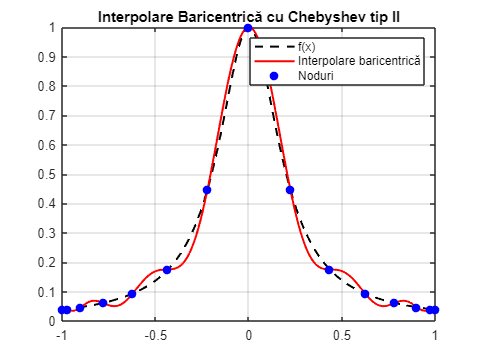


f = @(x) 1 ./ (1 + 25 * x.^2);
a = -1; b = 1; n = 15;

% Tipul nodurilor: 'I' sau 'II'
[xn, yn, w, xe, yeval, expr] = BaricentricaChebyshev(f, a, b, n, 'II');

% Plot
figure;
plot(xe, f(xe), 'k--', 'LineWidth', 1.5); hold on;
plot(xe, yeval, 'r-', 'LineWidth', 1.5);
plot(xn, yn, 'bo', 'MarkerFaceColor', 'b');
legend('f(x)', 'Interpolare baricentrică', 'Noduri');
title('Interpolare Baricentrică cu Chebyshev tip II');
grid on;